Definicja układu dynamiki:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \\
\left(x_1 +1\right)x_1 \left(x_1 -1\right)-x_2 
\end{array}\right\rbrack$$


syms x1 x2 real
f = [x2; (x1+1)*x1*(x1-1) - x2];

Definicja funkcji Lapunowa:


$$V(x) = \frac{x_2^2}{2} - \frac{x_1^4}{4}  + \frac{x_1^2}{2} $$


V = 0.5*x2^2 - 0.25*x1^4 + 0.5*x1^2;

Wyznaczenie pochodnej po trajektoriach systemu:

Vdot = simplify(gradient(V, [x1; x2])' * f);
fprintf("Pochodna po trajektoriach systemu: %s", string(Vdot));

Pochodna po trajektoriach systemu: -x2^2

Wyrysowanie portretu fazowego i funkcji Lapunowa oraz obszaru przyciągania:

[X1, X2] = meshgrid(-1.5:0.1:1.5);
dX1 = X2;
dX2 = (X1+1).*X1.*(X1-1) - X2;

Vfun = @(x1,x2)0.5*x2.^2 - 0.25*x1.^4 + 0.5*x1.^2;
Vnum = 0.5*X2.^2 - 0.25*X1.^4 + 0.5*X1.^2;
Vdotnum = -X2.^2;

figure();
grid on;
hold on;
xlabel("x_1");
ylabel("x_2");
title("Portret Fazowy");
xlim([-1.5, 1.5]);
ylim([-1.5, 1.5]);
legend("show");

quiver(X1, X2, dX1, dX2, 2, "DisplayName", "Pole wektorowe");

X0 = {[-1.5;1.5], [-1;1.5], [-0.5;1.5], [0;1.5], [0.5;1.5], [1;1.5], [1.5;1.5], ...
    [-1.5;-1.5], [-1;-1.5], [-0.5;-1.5], [0;-1.5], [0.5;-1.5], [1;-1.5], [1.5;-1.5], ...
    [-1.5;-1.5], [-1.5;-1], [-1.5;-0.5], [-1.5;0], [-1.5;0.5], [-1.5;1], [-1.5;1.5], ...
    [1.5;-1.5], [1.5;-1], [1.5;-0.5], [1.5;0], [1.5;0.5], [1.5;1], [1.5;1.5]};

f_num = @(t, x)[x(2);(x(1)+1)*x(1)*(x(1)-1) - x(2)];

for index = 1:length(X0)
    x0 = X0{index};
    [~, y] = ode45(f_num,0:0.1:10, x0);
    z = Vfun(y(:, 1), y(:, 2));
    plot3(y(:, 1), y(:, 2), z, "k", "HandleVisibility", "off");
end

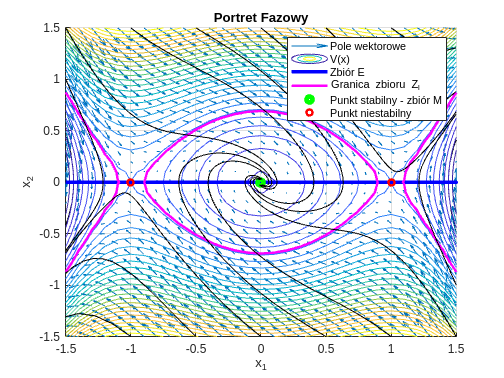

% Wyrysowanie funkcji Lapunowa
contour(X1, X2, Vnum, 30, "DisplayName", "V(x)");

% Zaznaczenie zbioru E
contour(X1, X2, Vdotnum, [0,0], "b", "LineWidth", 3, "DisplayName", "Zbiór E");

% Znalezienie zbioru M - największy inwariantny w E (czyli x1 \in R, x2 = 0)
% Musimy znaleźć gdzie x2' = 0, żeby pozostać na prostej x2 = 0
f_m = subs(f, {x2}, {0});
x2_dot = f_m(2);
x1_m = solve(x2_dot == 0, x1); % <- dostajemy trzy punkty równowagi, ale tylko (0,0) jest stabilny (z pośredniej metody)

% Wyrysowanie konturu obszaru przyciągania
l = 0.24;
contour(X1, X2, Vnum, [l,l], "m", "LineWidth", 2, "DisplayName", "Granica zbioru Z_l");

% Zaznaczenie punktów równowagi
plot(0, 0, "go", "MarkerSize", 5, "LineWidth", 4, "DisplayName", "Punkt stabilny - zbiór M");
plot([-1,1], [0,0], "ro", "MarkerSize", 5, "LineWidth", 2, "DisplayName", "Punkt niestabilny");